load('S01.mat')

trigger=data{1,1}.trial %start and stop signal 

trigger = 12×1 uint32 column vector
    238
    360
    639
    760
   1039
   1160
   1439
   1560
   1839
   1960


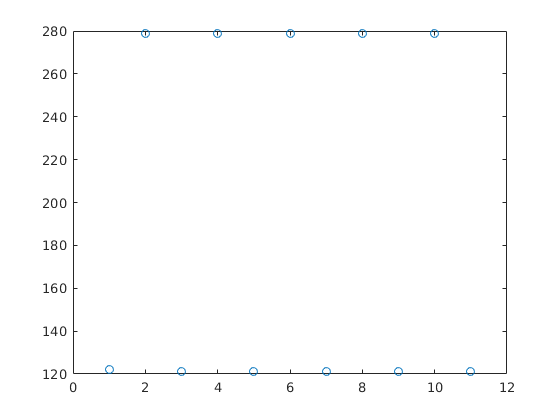

plot(diff(trigger),"o")

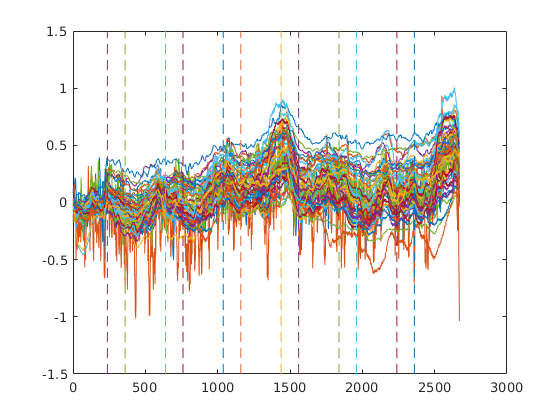

oxy=data{1,1}.X(:,1:52);
plot(oxy)
hold on
for l=trigger
    plot([l,l],[-1.5,1.5],"--")
end
hold off

Compute cusum

N=length(oxy(:,1))

N = 2671

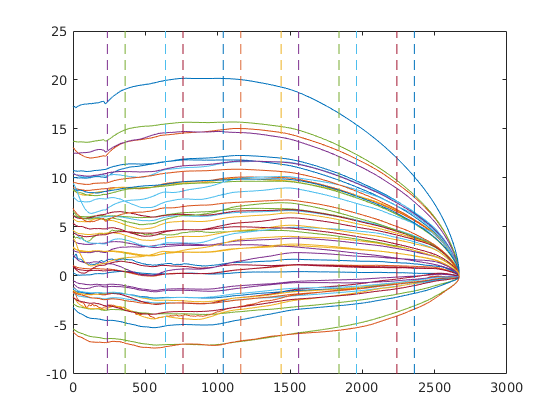

cusum_2nd=flipud(cumsum(flipud(oxy)));
t1=1:N-1;
cusum_1st=sqrt((N-1-t1)./((N-1)*t1))'.*cumsum(oxy(1:end-1,:));
t2=1:N-1;
cusum_2nd=cusum_2nd(2:end,:)*sqrt(t2/((N-t2)*N));
cusum=cusum_1st-cusum_2nd;
figure()
plot(cusum)


hold on
for l=trigger
    plot([l,l],[-10,25],"--")% it is the plot of vertical lines
end
hold off

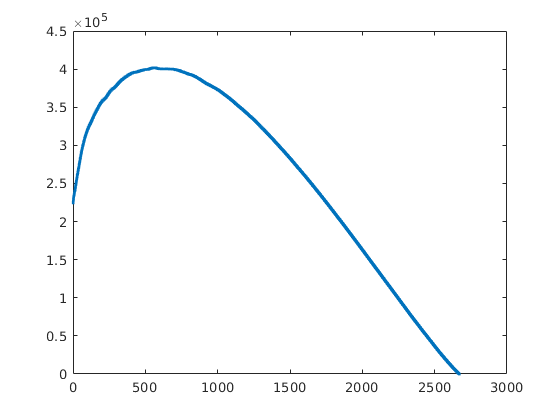

plot(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'),".")

[M,k]=max(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'))

M = 4.0171e+05

k = 563

[cusum, idx]=my_cusum(oxy);

N =         2671


M =    4.0171e+05


k =    563


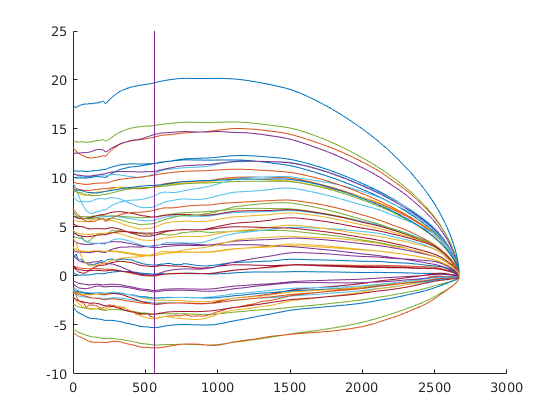

figure()
hold on
plot(cusum)
plot([idx,idx],[-10 25])
hold off

Select the region of interest

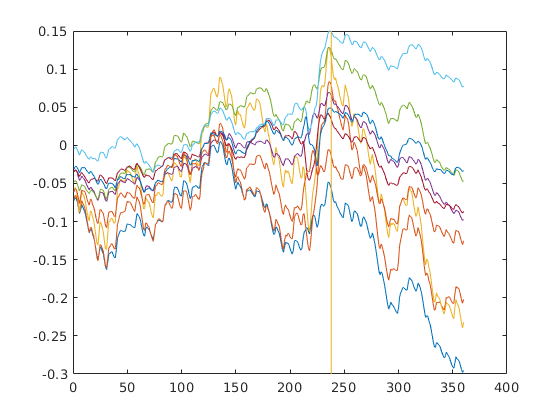

roi1=[46,47,48];
roi2=[18,28,29];
roi3=[13, 23, 24];
figure()
signal=oxy(1:trigger(2),[roi1 roi2 roi3]);
plot(signal)
hold on 
plot([238,238],[-.3 0.15])
hold off

## Change point detection

mean shift

N = 360

cusum_2nd =    -0.1178   -0.0851   -0.0409   -0.0184    0.0228    0.0506   -0.0188   -0.0075   -0.0546
   -0.1665   -0.1202   -0.0577   -0.0260    0.0325    0.0716   -0.0265   -0.0105   -0.0771
   -0.2039   -0.1471   -0.0705   -0.0317    0.0401    0.0879   -0.0323   -0.0128   -0.0943
   -0.2354   -0.1697   -0.0811   -0.0364    0.0467    0.1016   -0.0372   -0.0146   -0.1087
   -0.2630   -0.1895   -0.0903   -0.0405    0.0526    0.1139   -0.0414   -0.0161   -0.1213
   -0.2879   -0.2073   -0.0985   -0.0442    0.0581    0.1250   -0.0452   -0.0175   -0.1326
   -0.3108   -0.2236   -0.1060   -0.0474    0.0633    0.1353   -0.0486   -0.0187   -0.1429
   -0.3321   -0.2388   -0.1130   -0.0505    0.0681    0.1449   -0.0517   -0.0197   -0.1525
   -0.3521   -0.2530   -0.1195   -0.0533    0.0728    0.1539   -0.0546   -0.0207   -0.1615
   -0.3709   -0.2664   -0.1255   -0.0558    0.0773    0.1625   -0.0573   -0.0216   -0.1699


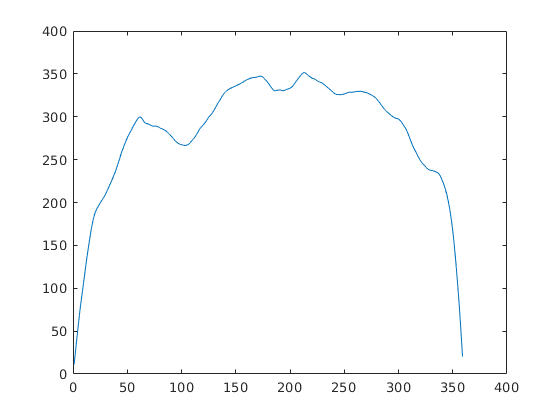

%[cusum, idx]=cusum_padding(oxy(1:trigger(2),1:end));
[cusum, mean_idx]=cusum_padding(signal);

mean and variance change

[C,var_idx]=cusum_covariance(signal);

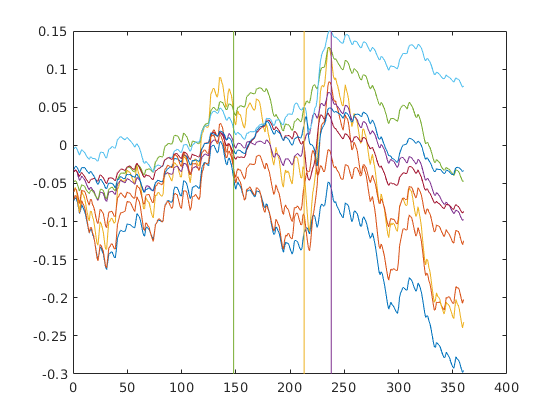

figure()
signal=oxy(1:trigger(2),[roi1 roi2 roi3]);
plot(signal)
hold on 
plot([mean_idx,mean_idx],[-.3 0.15])
plot([238,238],[-.3 0.15])
plot([var_idx,var_idx],[-.3 0.15])
hold off